% P9.5
clear all
syms s K tau_t tau_e tau_m Rs e_ss w

tau_t = 1.5;
tau_e = 4;
tau_m = 0.6;
Gc = 1/(tau_t*s+1);
G = K/(tau_e*s+1);
H = 1/(tau_m*s+1);
Ls = Gc*G*H             % Ls = Gc*G*H 이라 하자.

$$Ls = \frac{K}{\left(4\,s+1\right)\,\left(\frac{3\,s}{2}+1\right)\,\left(\frac{3\,s}{5}+1\right)}$$

Ts = simplify(Gc*G/(1+Ls))

$$Ts = \frac{2\,K\,\left(3\,s+5\right)}{36\,s^{3}+93\,s^{2}+61\,s+10\,K+10}$$

% (a)
eqn = e_ss == Rs - H*Gc*G*e_ss

$$eqn = e_{\mathrm{ss}}=\mathrm{Rs}-\frac{K\,e_{\mathrm{ss}}}{\left(4\,s+1\right)\,\left(\frac{3\,s}{2}+1\right)\,\left(\frac{3\,s}{5}+1\right)}$$

e_ss = simplify(limit(solve(eqn,e_ss),s,0))

$$e\_ss = \frac{\mathrm{Rs}}{K+1}$$

e_ss < 0.2*Rs

$$ans = \frac{\mathrm{Rs}}{K+1}<\frac{\mathrm{Rs}}{5}$$

% 위 부등식을 Rs>0, K>-1 이라고 가정하면, K>4 이다.

% (b)
[n, d] = numden(Ls);
eqn = d == 0;
s = solve(eqn,s)    % s = -2.5, -1, -0.333 (Ls의 양수부 pole은 0개이다.)

$$s = \left(\begin{array}{c} -\frac{5}{3}\\ -\frac{2}{3}\\ -\frac{1}{4} \end{array}\right)$$

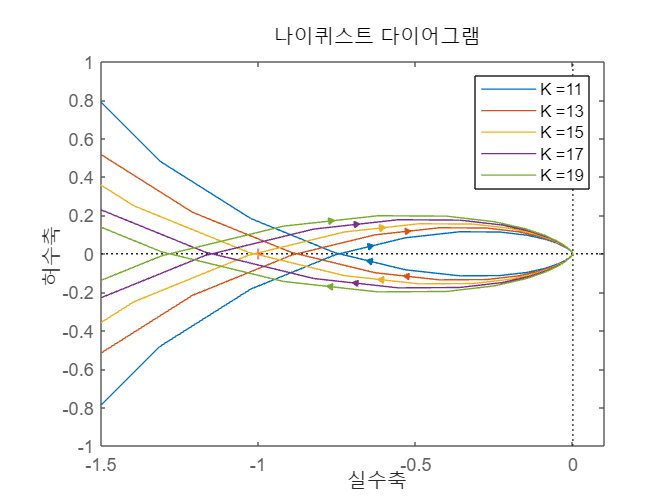


den = sym2poly(d);
sys_leg = [];
for K1 = 11:2:19
    num = sym2poly(subs(n,K,K1));
    sys_Ls = tf(num, den);
    nyquist(sys_Ls);

    K2 = string(K1);
    sys_leg1 = strcat('K = ',K2);
    sys_leg = cat(1,sys_leg,sys_leg1);
    hold on;
end
axis([-1.5 0.1 -1 1])
legend(sys_leg);
hold off


% (-1, 0)을 지나는 K 값을 구하는 함수 start
syms s
assume(w,'Real');
[num_T, den_T] = numden(subs(Ts,s,1i*w));
w_T = solve(real(den_T) == 0,w)

$$w\_T = \left(\begin{array}{c} \mathrm{root}\left(z^{3}-\frac{61\,z}{36}-\frac{5\,\mathrm{imag}\left(K\right)}{18},z,1\right)\\ \mathrm{root}\left(z^{3}-\frac{61\,z}{36}-\frac{5\,\mathrm{imag}\left(K\right)}{18},z,2\right)\\ \mathrm{root}\left(z^{3}-\frac{61\,z}{36}-\frac{5\,\mathrm{imag}\left(K\right)}{18},z,3\right) \end{array}\right)$$

K_discri = double(solve(subs(-93*w^2+10*K+10,w,w_T(3)),K));

K_discri = 14.7583

% (-1, 0)을 지나는 K 값을 구하는 함수 end

% K=14.7583 일 때는 nyquist 선도가 (-1,0)을 지나며,
% -1<K<14.7583 일 때는 nyquist 선도가 (-1,0)을 0번 둘러싸며,
% K>14.7583 일 때는 nyquist 선도가 (-1,0)을 시계 방향으로 2번 둘러싼다.
% 
% Ls의 양수부 pole이 0개이므로, 시스템이 안정적이기 위해서는
% nyquist 선도가 (-1,0)을 둘러싸면 안 된다.
% 따라서 시스템이 안정하며, 오차율이 20% 미만이기 위해서는
% 4<K<14.7583 이어야 한다.

% (c)
% 만약 K = 4 라면(오차율이 20%라면)
Ls = subs(Ls,K,4)   % Ls 의 여유를 구했을 때

$$Ls = \frac{4}{\left(4\,s+1\right)\,\left(\frac{3\,s}{2}+1\right)\,\left(\frac{3\,s}{5}+1\right)}$$

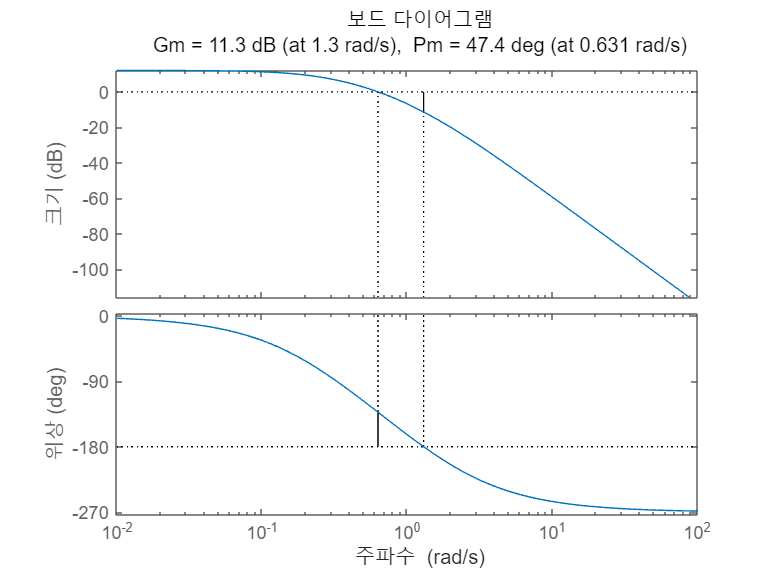

[n, d] = numden(Ls);
num = sym2poly(n);
den = sym2poly(d);
sys_Ls = tf(num, den);
margin(sys_Ls);

[Gm, Pm] = margin(sys_Ls)

Gm = 3.6896

Pm = 47.4174


Ts = subs(Ts,K,4)   % 궤환시스템(Ts)의 여유를 구했을 때

$$Ts = \frac{8\,\left(3\,s+5\right)}{36\,s^{3}+93\,s^{2}+61\,s+50}$$

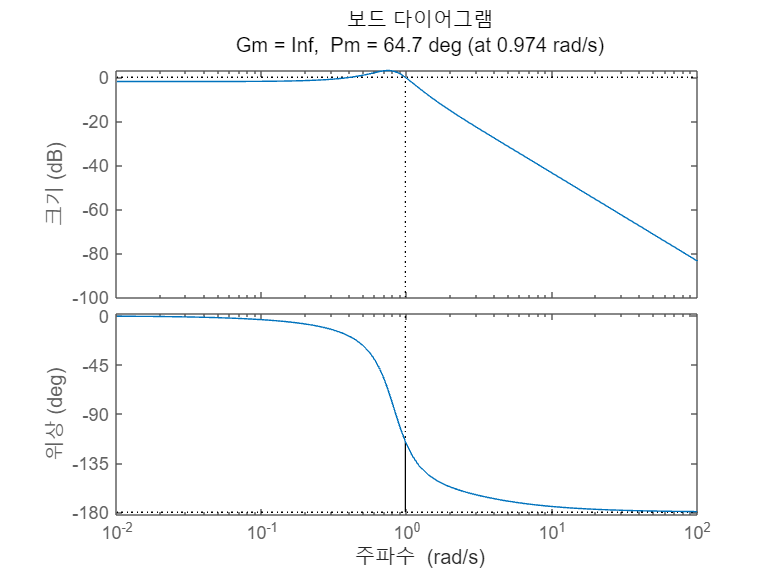

[n, d] = numden(Ts);
num = sym2poly(n);
den = sym2poly(d);
sys_Ts = tf(num, den);
margin(sys_Ts);

[Gm, Pm] = margin(sys_Ts)

Gm = Inf

Pm = 64.6640